# Exoplanet Transit Explorer

Explores original transit signal evidence for seven Earth-sized exoplanets planets in the Trappist-1 system. The data analysis methods developed here could be applied to other transit data.

This script downloads original data from Springer Nature [1] [2] who request I include the following disclaimer. 'Please do not use the script for purposes other than intended to download the data from the open paper.' 

The user is encouraged to study the original paper and follow-on studies found in the references.

Author: D. Carlsmith

## Introduction

If an exoplanet transits a host star along the line-of-sight, the apparent host star brightness is temporarily slightly decreased. This Live Script examines such exoplanet transit signals in TRAPPIST-1 luminance as seen by the [SpitzerSpace Telescope](https://en.wikipedia.org/wiki/Spitzer_Space_Telescope) using published data [1]. The script provides students of astronomy and physics an intimate look at such data and means to reproduce parts of the published scientific analysis. Several **Try this** suggestions are offered for further exploration.

 [TRAPPIST-1](https://en.wikipedia.org/wiki/TRAPPIST-1) is a low brightness dwarf star just some 37 LY from Earth (~10 times the distance to the nearest star) with seven Earth-sized planets called Trappist1(b-h) of which two may be "habitable." The host star mass has been estimated from its spectrum and the theory of stellar structure and evolution. From the periods between transits, given the host star mass, the planetary orbital radii are found using [Kepler's 3rd Law](https://en.wikipedia.org/wiki/Kepler%27s_laws_of_planetary_motion#Third_law). The depth of the apparent luminance dip during a transit depends upon planet area so the planet radii can be estimated. The planet masses (not estimated here) may be deduced from interplanetary gravitational interactions that disturb the periodicity of the transits. The length of the transit in time contains information about the orbital inclination (also not estimated here).

clear;

## Download data

The data is a spreadsheet of star brightness available at the source data link at [https://www.nature.com/articles/nature21360/figures/1.](https://www.nature.com/articles/nature21360/figures/1.) It may be downloaded directly using [`websave`](https://www.mathworks.com/help/matlab/ref/websave.html).

Set the URL for the file.

dataUrl="https://static-content.springer.com/esm/art%3A10.1038%2Fnature21360/MediaObjects/41586_2017_BFnature21360_MOESM81_ESM.xlsx";

Create a local data file name.

dataFile="TransitData.xlsx";

Save the data to the data file and return the full path to the file.

dataFileFullPath = websave(dataFile, dataUrl);

## Import the data

Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 3);

Specify sheet and range.

opts.Sheet = "Spitzer";
opts.DataRange = "A2:C12879";

Specify column names and types

opts.VariableNames = ["Time", "Flux", "Error"];
opts.VariableTypes = ["double", "double", "double"];

Import the data using [`readtable`](https://www.mathworks.com/help/matlab/import_export/read-spreadsheet-data-into-table.html).

tbl = readtable("41586_2017_BFnature21360_MOESM81_ESM.xlsx", opts, "UseExcel", false);
tbl = readtable(dataFile, opts, "UseExcel", false);

Convert table columns to vectors.

Time = tbl.Time;
Flux = tbl.Flux;
Error = tbl.Error;

Clear temporary variables

clear opts tbl

## Prepare data for analysis

 Sort data by time in increasing order. Imported `Time` is not sequential, and has gaps.

[Time,I]=sort(Time);
Flux=Flux(I);
Error=Error(I);

Adjust time offset in the data file to that used in Ref. [1]. 

Time=Time-2457600+2450000;

Time limits for observations.

MinTime=min(Time);MaxTime=max(Time);

Planet names, periods, and mid-transit times from Ref. [1].

Nplanet=7;
PlanetName=['b','c','d','e','f','g','h'];
Period=[1.51087637,2.42180746,4.049959,6.099043,...
    9.205585,12.354473,18.767953];
MidTransit=[7322.51736,7282.80728,7670.14165,...
    7660.37859,7671.39767,7665.34937,7662.55463];
MidTransit=MidTransit-2457600+2450000;

## Find expected transits within the observation window

`Planetn1`= no. of periods since reference mid-transit time for first transit in the observation window. 

`Planetn2`= no. of periods since reference mid-transit for last transit in the observation window.

Planetn1=zeros(1,Nplanet);Planetn2=zeros(1,Nplanet);
n1=-100;n2=500;
for iplanet=1:Nplanet    
    Planetn1(iplanet)=n1;Planetn2(iplanet)=n2;
    for n=n1:n2
        tTrans=MidTransit(iplanet)+n*Period(iplanet);
        if tTrans>MinTime&tTrans<MaxTime            
            if Planetn1(iplanet)==n1;
                Planetn1(iplanet)=n;
            end
            Planetn2(iplanet)=n;
        end
    end
end

## Plot flux from TRAPPIST-1 system over time

plot(Time,Flux,'.r')
title('The TRAPPIST-1 system as seen by Spitzer')
xlabel('BJD_{TBD}-2,457,600 (days)');
ylabel('Relative brightness')
hold on

Smooth the data with a linear fit over 4 bins to reduce noise a bit with [smoothdata](https://www.mathworks.com/help/matlab/ref/smoothdata.html#bvhejau-method).

SFlux=smoothdata(Flux,'lowess',4);

### **Try this:** Change the smoothing algorithm.

%[SFlux,window]=smoothdata(Flux,'gaussian');

Superpose smoothed flux.

plot(Time,SFlux,'.b')
legend('raw','smoothed')
hold on

Place a centered label under each transit in the observation window.

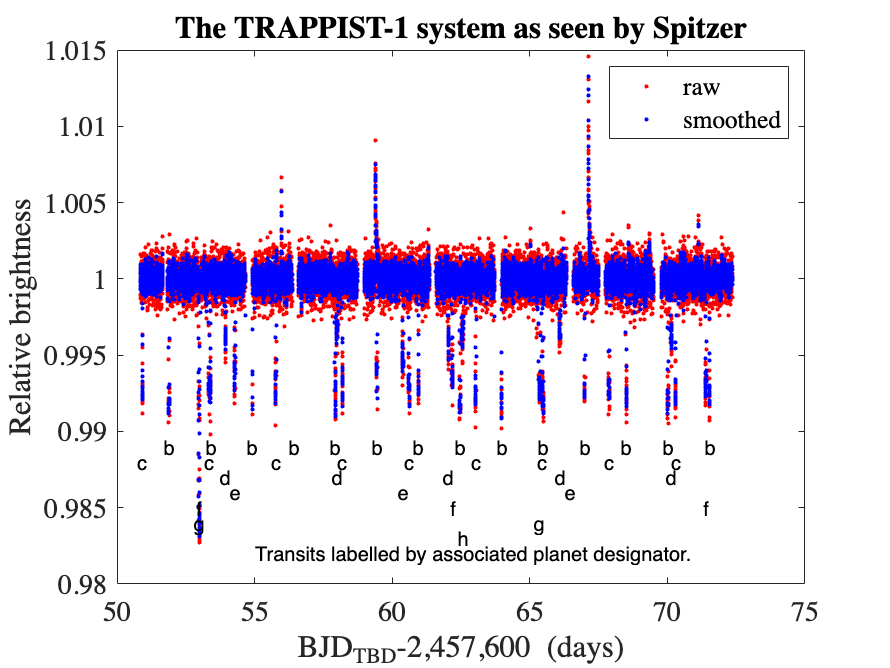

for iplanet=1:Nplanet
    for n=Planetn1(iplanet):Planetn2(iplanet)
        ttrans=MidTransit(iplanet)+n*Period(iplanet);
        f=.99-.001*iplanet;
        text(ttrans,f,PlanetName(iplanet),...
            'HorizontalAlignment','center');
    end
end
text(55,0.982,'Transits labelled by associated planet designator.')
hold off

We observe a relative brightness noise standard deviation of  ~0.001, about 30 transit signals with 0.005 day durations and ~1% flux decrease, and a few flares (above normal brightness). There are also gaps in the data. Note that the first f and g transit signals overlap. Two transits are half-lost to gaps in the observations.

### **Try this**: Zoom into the above plot to examine each of the transits in detail.

Zoom view of a flare.

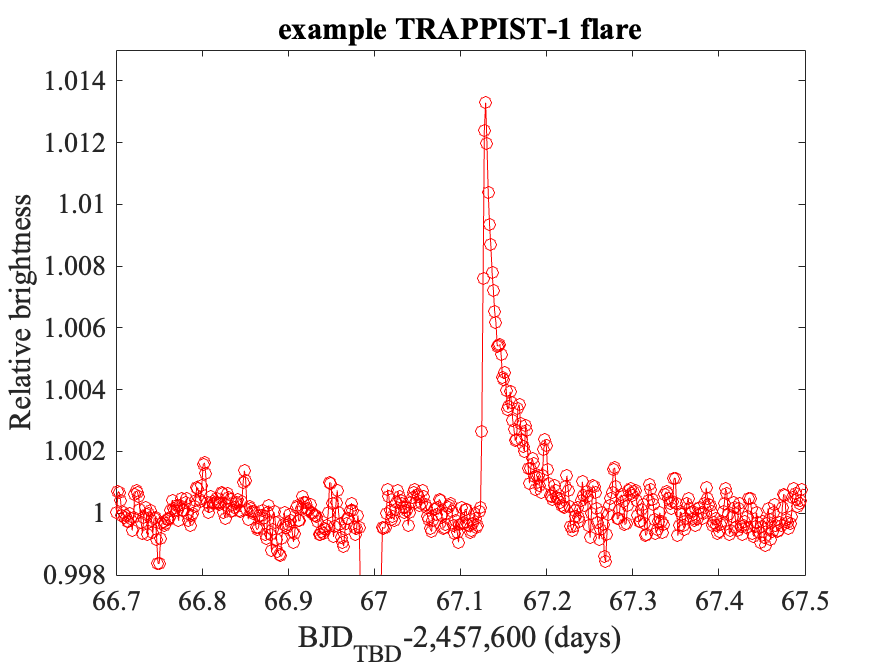

figure
plot(Time,SFlux,'o-r')
title('example TRAPPIST-1 flare')
xlabel('BJD_{TBD}-2,457,600 (days)');
ylabel('Relative brightness')
xlim([66.7,67.5]);ylim([0.998,1.015])

Zoom view of a transit.

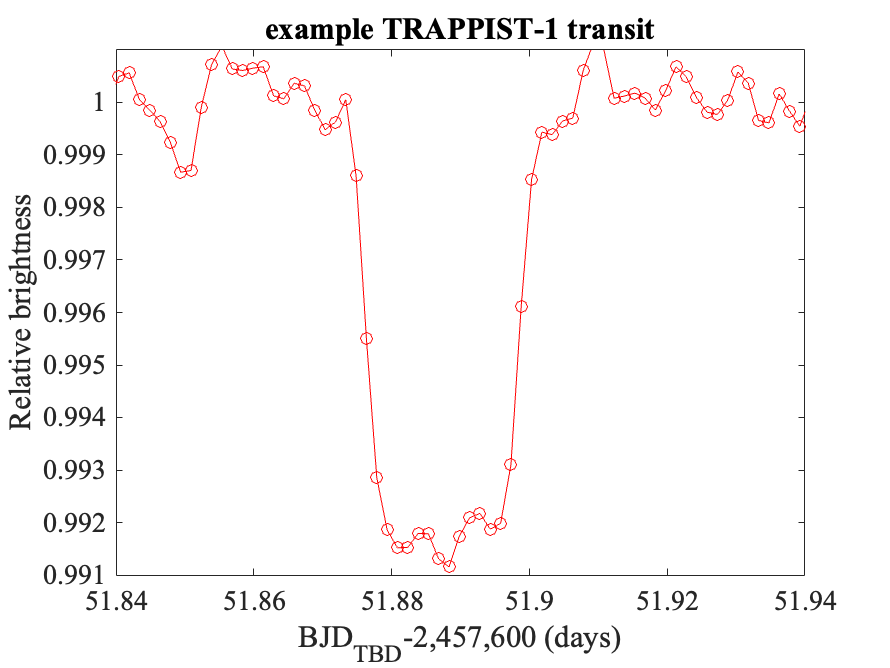

figure
plot(Time,SFlux,'o-r')
title('example TRAPPIST-1 transit')
xlabel('BJD_{TBD}-2,457,600 (days)');
ylabel('Relative brightness')
xlim([51.84,51.94]);ylim([0.991,1.001])

## Locate transit signals

We are interested in the regions where the relative brightness drops below noise level. Get the standard deviation of the noise from data near unit relative flux.

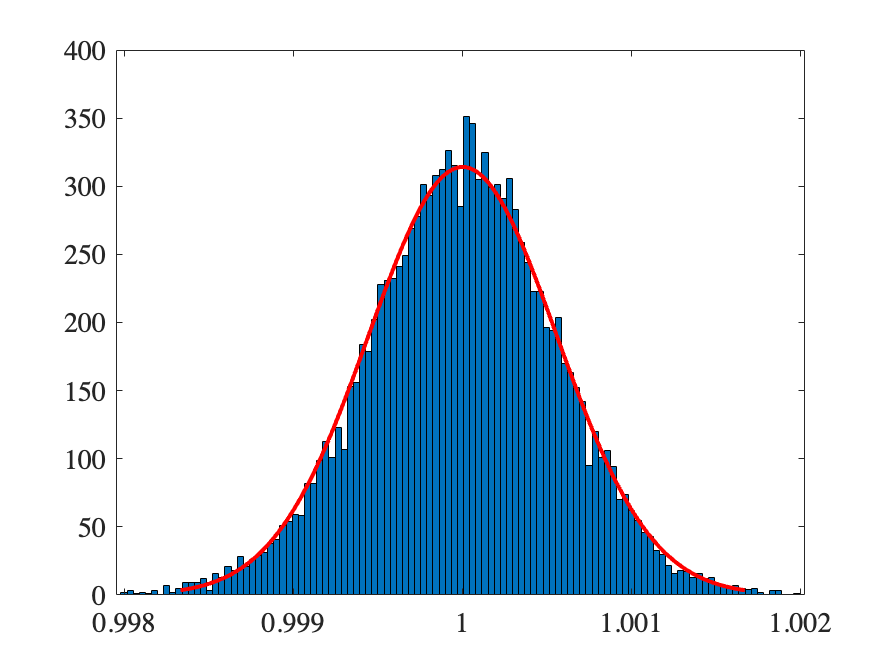

figure
mask=SFlux<1.002&SFlux>.998;
histfit(SFlux(mask))

We observe the noise is quite gaussian. Fit for the standard deviation and mean.

pd = fitdist(SFlux(mask),'Normal')

pd =   NormalDistribution

  Normal distribution
       mu =           1   [0.999992, 1.00001]
    sigma = 0.000556373   [0.000549452, 0.000563472]


Create a data selection mask to select points with relative flux at least a few std below unity. The mask will contain strings of logical true values during transits and logical zero values where there is no brightness dip associated with a transit. This selection ignores possible transits during flares, and shallow transits (small planets) below the noise threshold.

Set the noise threshold in units of noise standard deviation.

### Try this: Vary the noise threshold to study the sensitivity of the results to this threshold.

noisethreshold=4.0;

Create the mask.

mask=SFlux<1-noisethreshold*pd.sigma&SFlux>0.1;

Use [`bwareaopen`](https://www.mathworks.com/help/images/ref/bwareaopen.html) to remove any single points (points with no neighbor points) that could appear due to noise fluctuations/outliers. 

mask=bwareaopen(mask,2);

Remove two no data regions identified by hand.

mask=mask&~(Time>54.5&Time<55)&~(Time>63.7&Time<64);

Remove (with 20/20 hindsight) overlapping transits of f and g.

mask=mask&~(Time>52.96&Time<53.04);
dmask=double(mask);

Get connected components in the mask array. Each will be identified as a single transit event. We use [bwconncomp](https://www.mathworks.com/help/images/ref/bwconncomp.html) on the 1d array `mask,` catching a structure `CC` which contains the information we need.

`CC.NumObjects` is the number of connected components/transits found.

CC=bwconncomp(mask);
N=CC.NumObjects

N =     31


`CC.PixelIdxList(i)` is a cell array containing the indices in mask for the i-th transit. The lowest and highest values point to the start and stop times for the transit. 

Loop over connected components (transits) and extract the transit length as the length of the component, the mid-transit time as the average of the component end-points, and the average flux from the central region of the component.

transitPlanet=zeros(N,1);
transitPeriod=zeros(N,1);
transitTDiff=100*ones(N,1);
transitCenterIndex=ones(N,1);
for itrans=1:N
    transitIndices=cell2mat(CC.PixelIdxList(itrans));
    t1=transitIndices(1);t2=transitIndices(end);
    transitLength(itrans)=Time(t2)-Time(t1);
    transitTime(itrans)=(Time(t2)+Time(t1))/2;    

Compute average flux neglecting/trimming away `m` points on either edge of the flux dip.

    m=3;

### Try this: Change m to change the range over which the average flux is found.

    transitFlux(itrans)=sum(SFlux(t1+m:t2-m))/(t2-t1-2*m+1);

For each transit found in the data, find the closest predicted transit and store the planet numbers `transitPlanet`, period numbers `transitPeriod`, and the transit time deviations (mid-transit estimate minus mid-transit predicted values) `transitTDiff`.

    for iplanet=1:Nplanet
        for n=Planetn1(iplanet):Planetn2(iplanet)
            ttrans=MidTransit(iplanet)+n*Period(iplanet);
            TDiff=transitTime(itrans)-ttrans;
            if abs(TDiff)<abs(transitTDiff(itrans))
                transitPlanet(itrans)=iplanet;
                transitPeriod(itrans)=n;
                transitTDiff(itrans)=TDiff;  
                for it=1:length(Time)
                    if abs(Time(it)-ttrans)<...
                            abs(Time(transitCenterIndex(itrans))-ttrans)
                        transitCenterIndex(itrans)=it;
                    end
                end
            end
        end 
       
    end
end

Overlay smoothed selected transit signal flux atop smoothed data flux and show mask values to visually indicate the windows of good transit data found. We put a hold on the plot until we have added markers for mean flux at the depth of each transit.

figure
plot(Time,SFlux,'.b','DisplayName','all data')
hold on
plot(Time(mask),SFlux(mask),'.r','DisplayName','transit data')
hold on
plot(Time,dmask,'DisplayName','transit window')
hold on

Overlay markers in plot showing mean transit times located and average fluxes.

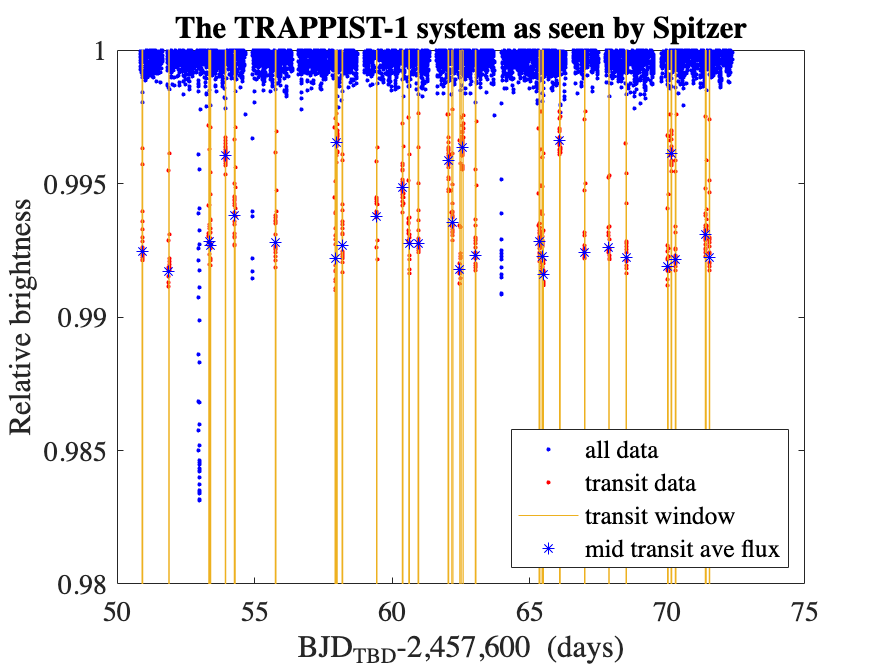

plot(transitTime,transitFlux,'*b','DisplayName','mid transit ave flux')
ylim([.98,1])
hold off
legend('Location','southeast')
title('The TRAPPIST-1 system as seen by Spitzer')
xlabel('BJD_{TBD}-2,457,600 (days)');
ylabel('Relative brightness')

### **Try this**: Are there any transits during flares or shallow transits? Zoom and pan above to check.

## Check transit time deviations

Fit to a normal distribution the distribution of time differences between transit midpoints and predicted values.

Note that interplanetary gravitational interactions lead to transit time variations (TTVs) which can be of order the transit times in this compact system.

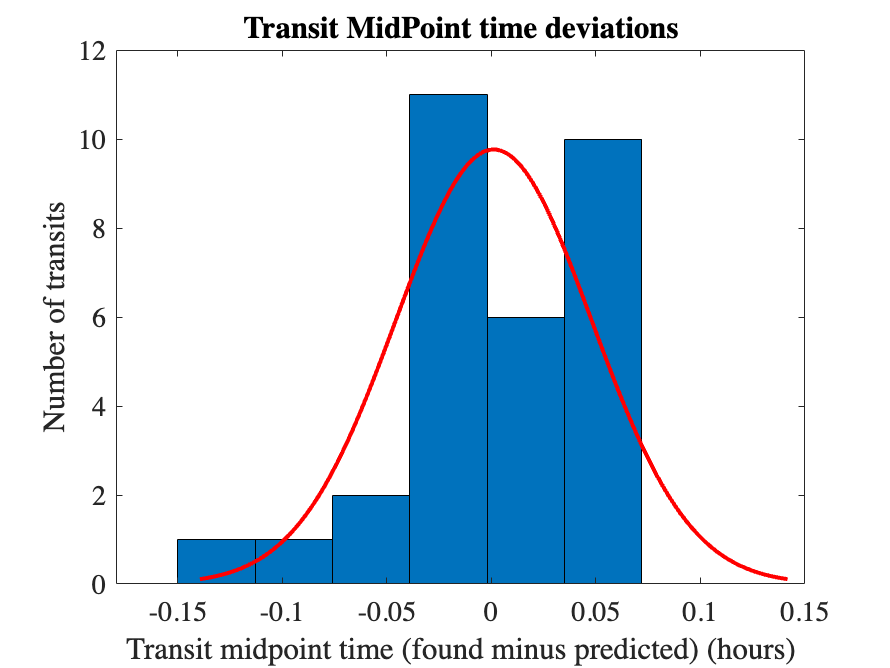

figure
histfit(transitTDiff*24)
title('Transit MidPoint time deviations')
xlabel('Transit midpoint time (found minus predicted) (hours)');ylabel('Number of transits')

We see the deviations between the midpoint times found by our method and the predicted midpoint times are of order 5% of the transit widths, comparable to the time quantization uncertainty, but a few are larger and may result from overlapping transits or TTVs.

pd=fitdist(transitTDiff,'normal')

pd =   NormalDistribution

  Normal distribution
       mu = 4.50982e-05   [-0.000671027, 0.000761223]
    sigma =  0.00195234   [0.00156014, 0.00260964]


Scatter plot transit time, length, and flux in 3d to look for correlations. Use the planet number (`transitPlanet`)as an index into a colormap to make a distinguishing color for each planet.

### **Try this**: Tilt and twirl the 3d plot.

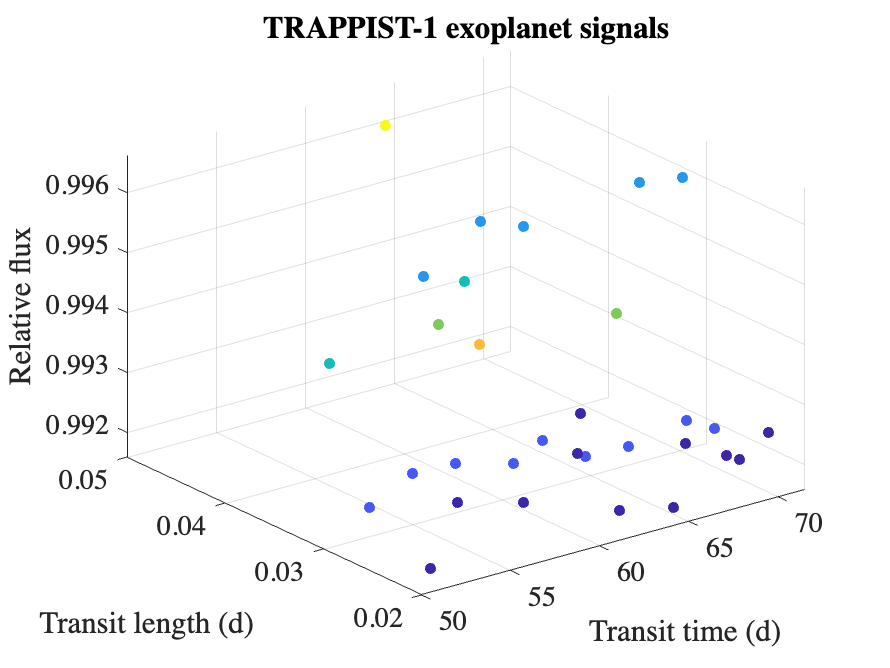

S=30*ones(1,length(transitLength)); % circle sizes
figure
scatter3(transitTime,transitLength,transitFlux,S,transitPlanet,'filled')
colormap('parula')
xlabel('Transit time (d)');ylabel('Transit length (d)')
zlabel('Relative flux')
title('TRAPPIST-1 exoplanet signals')

### Try this: Try a kmeans clustering algorithm to attempt to identify planets

% X=[transitTime' transitLength' transitFlux'];
% idx = kmeans(X, 7); % 3 number of classes
% scatter3(X(:,1), X(:,2), X(:,3), 15, idx, 'filled');

Make a [3d gscatter](https://www.mathworks.com/matlabcentral/answers/92577-how-can-i-create-a-3d-grouped-scatter-plot-in-statistics-toolbox-7-2-r2009b) plot by using [gscatter](https://www.mathworks.com/help/stats/gscatter.html) to scatter data in 2d with different groups (planets) given different colors, and then setting the the z-values according to flux.

figure

Call gscatter and capture output argument (handles to lines).

transitPlanetName=PlanetName(transitPlanet); 
h = gscatter(transitTime, transitLength, transitPlanet);

For each unique group in `transitFlux`, set the ZData property appropriately and capture a legend label.

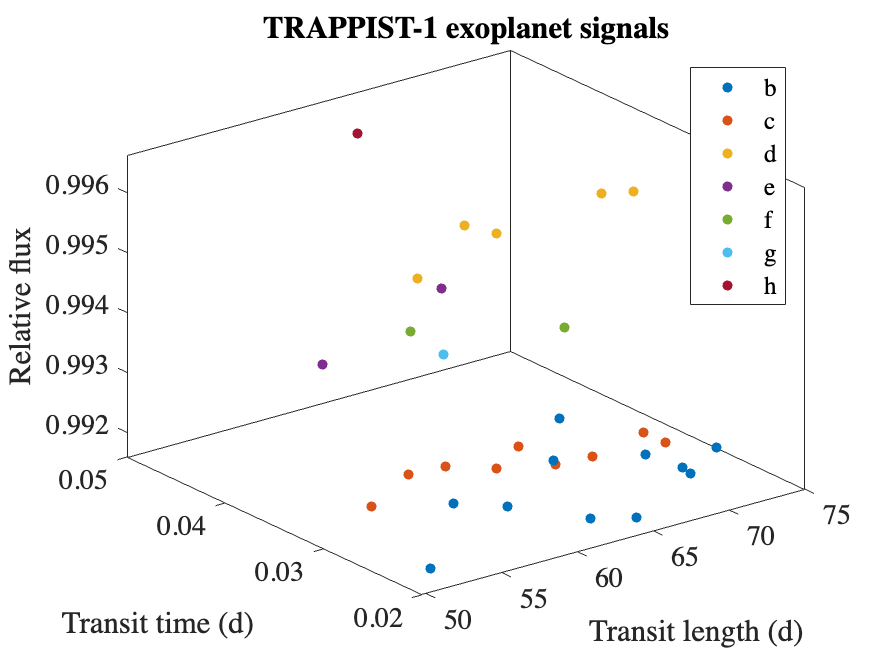

gu = unique(transitPlanet);
leg=[];
for k = 1:numel(gu)
      set(h(k), 'ZData', transitFlux( transitPlanet == gu(k) ));
      leg=cat(1,leg,PlanetName(k));
end
view(3)
zlabel('Relative flux')
xlabel('Transit length (d)');ylabel('Transit time (d)')
legend(leg)
title('TRAPPIST-1 exoplanet signals')

A given planet should have a fixed transit length and relative flux. The data is too noisy to pick out the transits of individual planets on the basis of transit length and depth alone.

### **Try this:** Write a sieve to identify the various planets based on the mid transit times, allowing for missed observations.

See Ref [3].

## Fold identified transit signals

Loop over planets and merge associated transit data into an array `transFoldedFlux.`

dtime=Time(3)-Time(2);
ntrans=zeros(1,Nplanet);
window = fix(max(transitLength)/dtime);
transitFoldedFlux=zeros(Nplanet,2*window+1);
for iplanet=1:Nplanet
   
    for itrans=1:N
        if transitPlanet(itrans)==iplanet
            ntrans(iplanet)=ntrans(iplanet)+1;
            jtime=0;
            for itime=-window:window
                jtime=jtime+1;
                transitFoldedFlux(iplanet,jtime)=transitFoldedFlux(iplanet,jtime)...
                    +Flux(transitCenterIndex(itrans)+itime);
            end
        end
    end
    if ntrans(iplanet)>0
        transitFoldedFlux(iplanet,:)=transitFoldedFlux(iplanet,:)/ntrans(iplanet);
    end
end

## Find depths of folded transit signals using [statelevels](https://www.mathworks.com/help/signal/ref/statelevels.html).

PlanetLevels=zeros(Nplanet,2);
for iplanet=1:Nplanet
    LEVELS = statelevels(transitFoldedFlux(iplanet,:));
    PlanetLevels(iplanet,:)=LEVELS;
end

## Plot folded transit signals

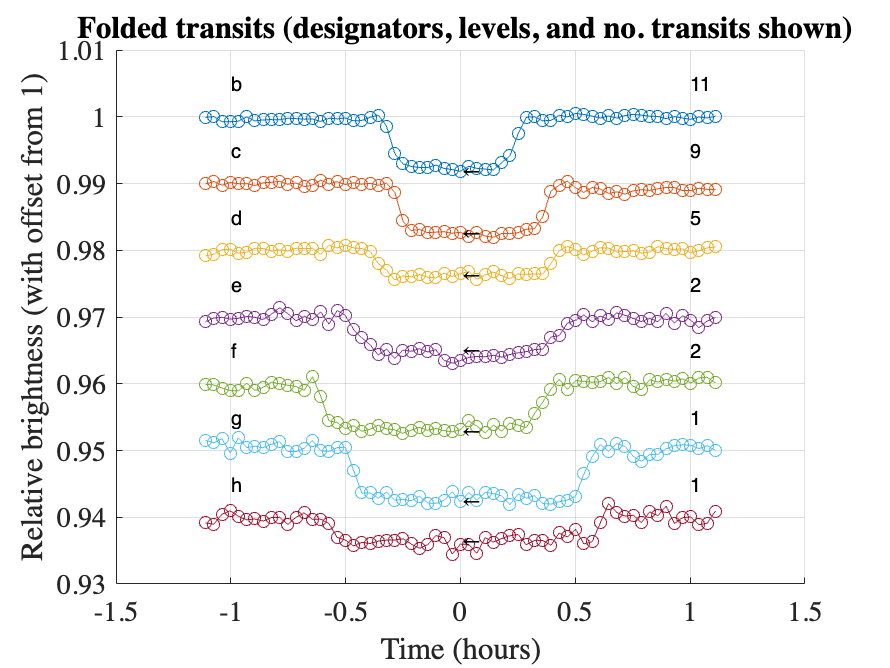

figure
hold on
tim=[-window:window]*dtime*24;
for iplanet=1:Nplanet
    offset=-(iplanet-1)*0.01;
    plot(tim,offset+transitFoldedFlux(iplanet,:),'o-')
    text(-1.,1+offset+.005,string(PlanetName(iplanet)))
    text(+1.,1+offset+.005,num2str(ntrans(iplanet)))
    text(0.,offset+PlanetLevels(iplanet,1),'\leftarrow ')
    hold on
end

title(' Folded transits (designators, levels, and no. transits shown)')
xlabel('Time (hours)');ylabel('Relative brightness (with offset from 1)') 
grid on  
hold off

## Compute orbital radii from [Kepler's Law](https://en.wikipedia.org/wiki/Kepler%27s_laws_of_planetary_motion)

Kepler's law relates period $T$ to semi major axis $a$ as $T^2=(4\pi^2/GM_{Trappist})a^3$.

G_N=6.674e-11;              % Newton's gravitational constant (SI units)
R_Sun=695.51e6;             % Radius of the Sun
M_Sun = 1.989e+30;          % Mass of the Sun
AU=1.496e+11;               % Earth's mean orbital radius
R_Trappist=0.12*R_Sun/AU;   % Radius of Trappist-1
M_Trappist = 0.089*M_Sun;   % Mass of Trappist-1

PlanetOrbitalRadius=((G_N*M_Trappist/(4*pi^2))*(Period*86400).^2).^(1/3)/AU;

## Compute planetary radii from transit depths

Assuming light is decreased in proportion to planet area, the transit depth 1-PlanetLevel(iplanet,2) = (R_Planet/R_Trappist)^2

R_Planet= R_Trappist*(1.-PlanetLevels(:,1)).^(1/2);

## Visualize the planetary system

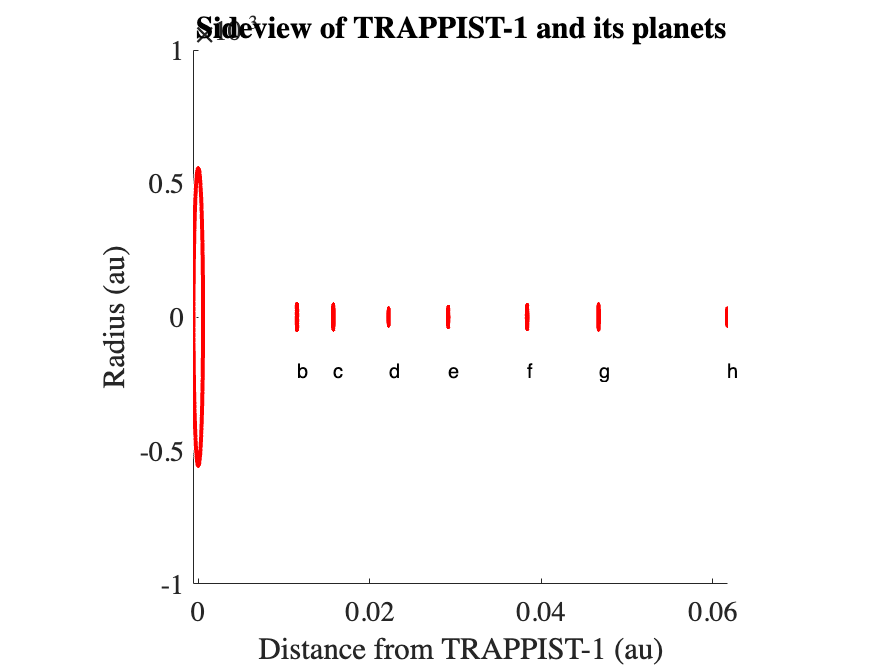

figure
centers=zeros(Nplanet+1,2);
centers(:,1)=[0;PlanetOrbitalRadius'];
radii=[R_Trappist;R_Planet];
viscircles(centers,radii);
axis square
ylim([-.001,.001])
for iplanet=1:Nplanet
    text(PlanetOrbitalRadius(iplanet),-.2e-3,string(PlanetName(iplanet)))
end
xlabel('Distance from TRAPPIST-1 (au)');ylabel('Radius (au)')
title('Sideview of TRAPPIST-1 and its planets')

For additional updated information, see Ref. [5].

license('inuse')

image_toolbox
matlab
signal_toolbox
statistics_toolbox
symbolic_toolbox


version

ans = '9.12.0.1884302 (R2022a)'

## References

1) Gillon, M., Triaud, A., Demory, B. *et al.* Seven temperate terrestrial planets around the nearby ultracool dwarf star TRAPPIST-1. *Nature* **542, **456–460 (2017)  doi:10.1038/nature21360  [https://www.nature.com/articles/nature21360/figures/1](https://www.nature.com/articles/nature21360/figures/1) 

2) Requests for information concerning permissible data and script use may be directed to Paloma Hammond, Rights executive, SpringerNature**, **The Campus, 4 Crinan Street, London N1 9XW, United Kingdom, paloma.hammond@springernature.com

3) Gillon, M. et al, Temperate Earth-sized planets transiting a nearby ultracool dwarf star, [Nature. 2016 May 12; 533(7602): 221–224. ](https://www.ncbi.nlm.nih.gov/entrez/eutils/elink.fcgi?dbfrom=pubmed&retmode=ref&cmd=prlinks&id=27135924) doi: [10.1038/nature17448](https://dx.doi.org/10.1038%2Fnature17448)[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5321506/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5321506/) 

4) Michael Hippke and René Heller, Optimized transit detection algorithm to search for periodic transits of small planets, A&A, 623  (2019) A39, DOI: https://doi.org/10.1051/0004-6361/201834672,[https://www.aanda.org/articles/aa/full_html/2019/03/aa34672-18/aa34672-18.html](https://www.aanda.org/articles/aa/full_html/2019/03/aa34672-18/aa34672-18.html) 

5) E. Ducrot, M. Sestovic, B. M. Morris, M. Gillon, A. H. M. J. Triaud, J. De Wit5 D. Thimmarayappa, E. Agol, Y. Almleaky, A. Burdanov, The 0.8–4.5 *μ*m Broadband Transmission Spectra of TRAPPIST-1 Planets,[The Astronomical Journal](https://iopscience.iop.org/journal/1538-3881),  [Volume 156](https://iopscience.iop.org/volume/1538-3881/156), [Number 5](https://iopscience.iop.org/issue/1538-3881/156/5), [https://iopscience.iop.org/article/10.3847/1538-3881/aade94/meta](https://iopscience.iop.org/article/10.3847/1538-3881/aade94/meta) 

6) Simon L.  Grimm, Brice-Olivier  Demory, Michaël  Gillon, Caroline  Dorn, Eric  Agol, Artem  Burdanov, Laetitia  Delrez, Marko  Sestovic, Amaury H. M. J.  Triaud, Martin  Turbet, Émeline  Bolmont, Anthony  Caldas, Julien  de Wit, Emmanuël  Jehin, Jérémy  Leconte, Sean N.  Raymond, Valérie  Van Grootel, Adam J.  Burgasser, Sean  Carey, Daniel  Fabrycky, Kevin  Heng, David M.  Hernandez, James G.  Ingalls, Susan  Lederer, Franck  Selsis, Didier  Queloz, The nature of the TRAPPIST-1 exoplanets. A&A 613 A68 (2018), DOI: 10.1051/0004-6361/201732233, [https://www.aanda.org/articles/aa/full_html/2018/05/aa32233-17/aa32233-17.html](https://www.aanda.org/articles/aa/full_html/2018/05/aa32233-17/aa32233-17.html) 